## Investigation of impact of roll-off factor

The final block in the DVB-S2 transmission system is a Root-Raised-Cosine Filter for pulse shaping. This has the effect of increasing the total bandwidth of the transmission based on the roll-off factor. Therefore, the maximum symbol rate can be calculated for the target bandwidth for each value of roll-off in the standard. 

modtable = readtable("Rs2Rb.csv");

Bandwidth =150000

Bandwidth = 150000

alphas = [0.35;0.25;0.20];
alpha = 0.35

alpha = 0.3500

Rs = 150e3 / (1 + alpha)

Rs = 1.1111e+05

bitsPerSymbol = 5

bitsPerSymbol = 5

ratesCells = unique(modtable.CodingRate);
rateVals = double(string(ratesCells).split("/"));
rates = rateVals(:,1) ./ rateVals(:,2)

rates =     0.5000
    0.3333
    0.2500
    0.6667
    0.4000
    0.7500
    0.6000
    0.8000
    0.8333
    0.8889



codingRate    = rates(3)

codingRate = 0.2500

bitrate = Rs*bitsPerSymbol*double(codingRate)

bitrate = 1.3889e+05

bitrate_kb = bitrate/1024

bitrate_kb = 135.6337


fprintf("Bitrate = %2f kbps for: \n" + ...
            "   Alpha = %2f  \n" + ...
            "   Bandwidth = %2f  \n" + ...
            "   BitsPerSymbol = %2f  \n" + ...
            "   Coding Rate = %2f",bitrate_kb, alpha, Bandwidth, bitsPerSymbol, codingRate)

Bitrate = 135.633681 kbps for: 
   Alpha = 0.350000  
   Bandwidth = 150000.000000  
   BitsPerSymbol = 5.000000  
   Coding Rate = 0.250000

### Plotting resulting bitrates 

modcods = string(modtable.Modulation) + " " + string(modtable.CodingRate);
modcod_Cat = categorical(modcods);
modcod_Cat = reordercats(modcod_Cat,modcods)

modcod_Cat = 28×1 categorical array
     QPSK 1/4 
     QPSK 1/3 
     QPSK 2/5 
     QPSK 1/2 
     QPSK 3/5 
     QPSK 2/3 
     QPSK 3/4 
     QPSK 4/5 
     QPSK 5/6 
     QPSK 8/9 
     QPSK 9/10 
     8PSK 3/5 
     8PSK 2/3 
     8PSK 3/4 
     8PSK 5/6 
     8PSK 8/9 
     8PSK 9/10 
     16APSK 2/3 
     16APSK 3/4 
     16APSK 4/5 
     16APSK 5/6 
     16APSK 8/9 
     16APSK 9/10 
     32APSK 3/4 
     32APSK 4/5 
     32APSK 5/6 
     32APSK 8/9 
     32APSK 9/10 


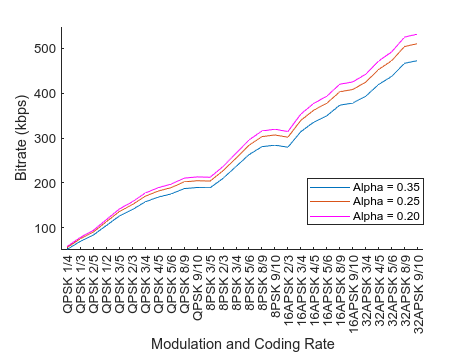

figure
hold on
%alpha 0.35
plot(modcod_Cat,modtable.Datarate_kbps____0_35_);
plot(modcod_Cat,modtable.Datarate_kbps____0_25_);
plot(modcod_Cat,modtable.Datarate_kbps____0_20_,"Color","magenta");

xlabel("Modulation and Coding Rate");
ylabel("Bitrate (kbps)")
legend(["Alpha = 0.35", "Alpha = 0.25", "Alpha = 0.20"], "Position", [0.6543 0.3621 0.2507, 0.1335])


hold off